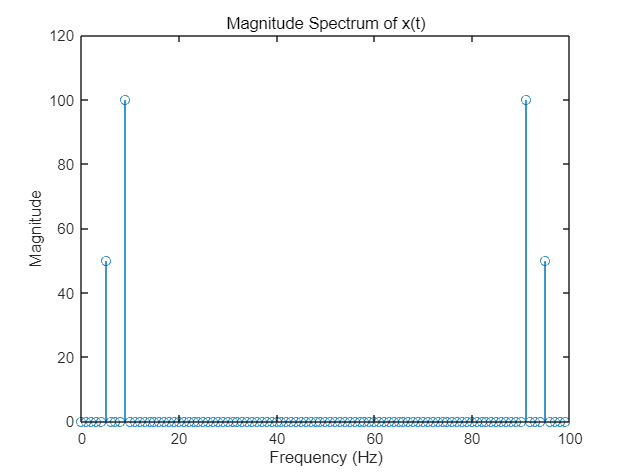

fs = 100; 
t = 0:1/fs:1-1/fs; 

x_t = cos(10*pi*t) + 2*sin(18*pi*t);
N = length(x_t); 
X_f = fft(x_t, N);
f = (0:N-1)*(fs/N);
figure;
stem(f, abs(X_f));
title('Magnitude Spectrum of x(t)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

T1 = 1/5; 
T2 = 1/9; 


T_lcm = lcm(sym(1/5), sym(1/9));
analysis_length = double(T_lcm) * fs; 

disp(['For minimal spectral leakage, choose an analysis length of ', num2str(analysis_length), ' samples.']);

For minimal spectral leakage, choose an analysis length of 100 samples.